testImageIdx = 1

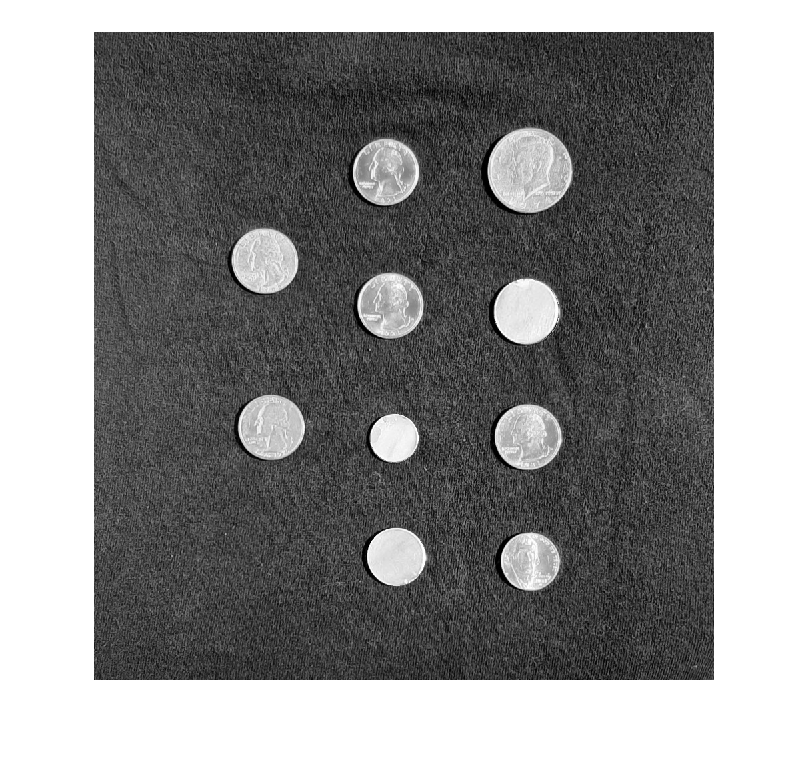

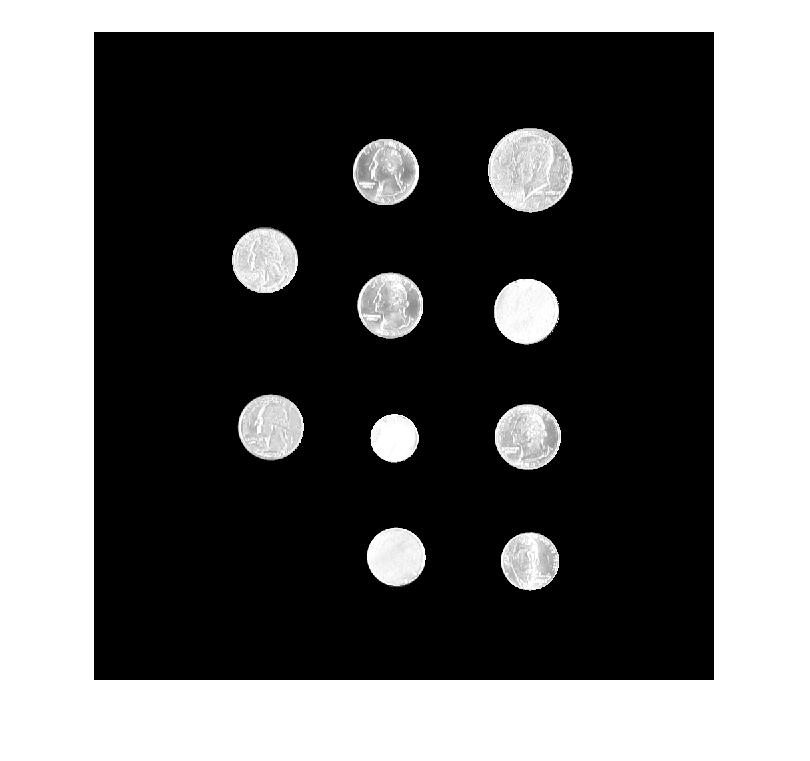

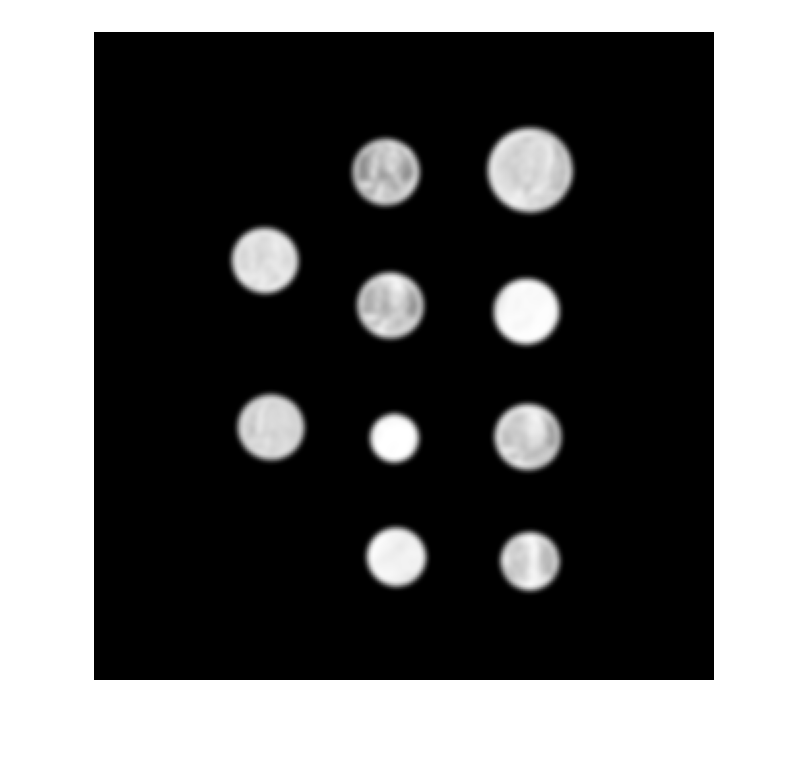

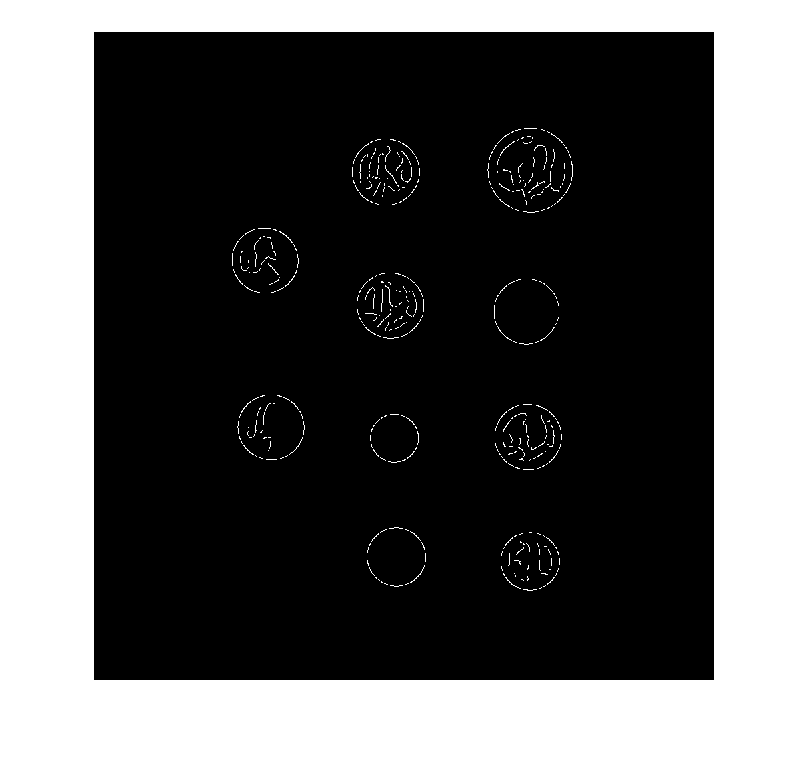

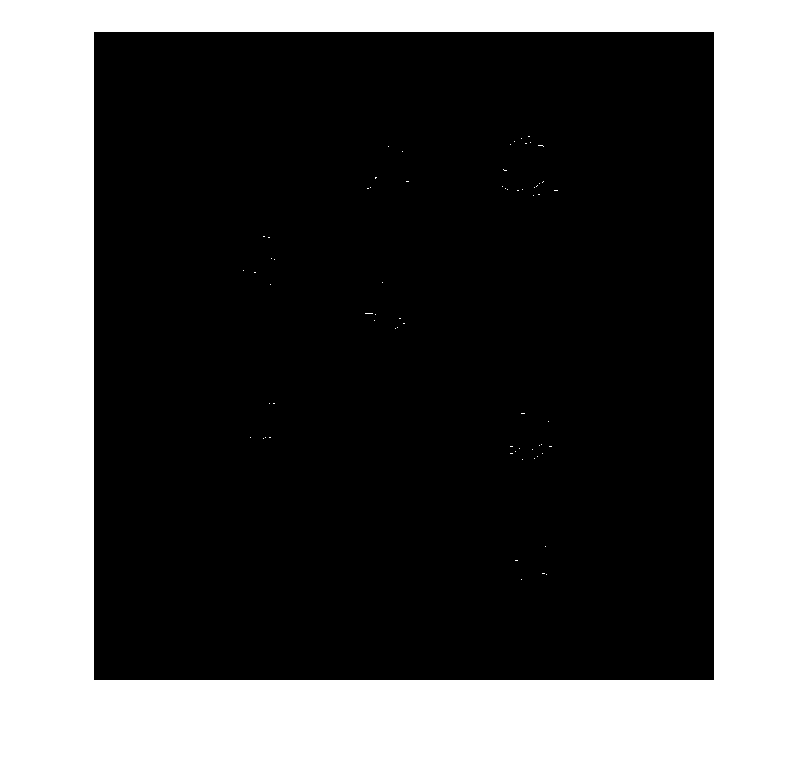

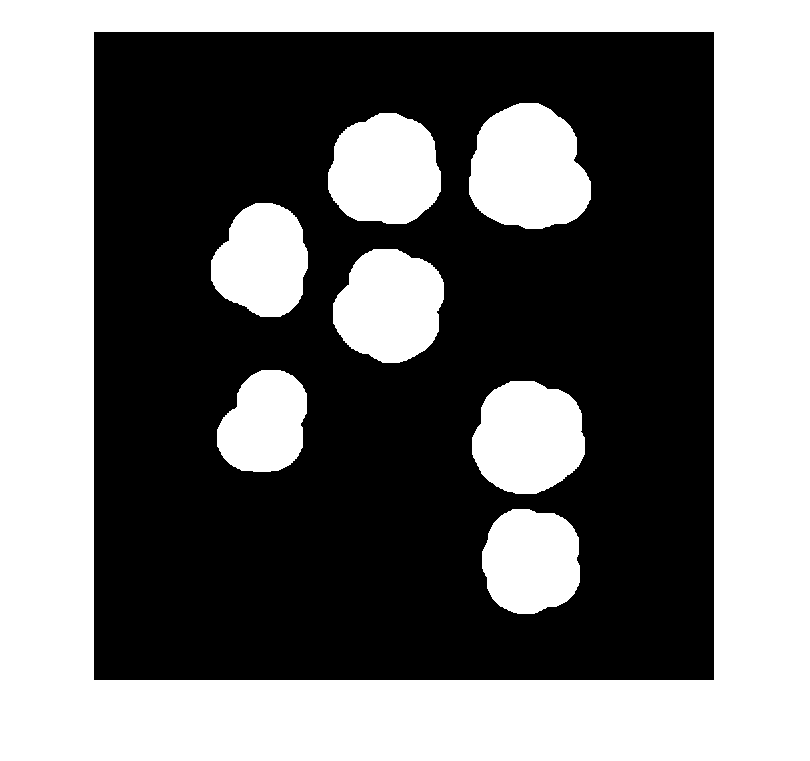

ans =   Group with properties:

    Children: [2×1 Line]
     Visible: on
     HitTest: on

  Show all properties


CC = struct with fields:
    Connectivity: 8
       ImageSize: [972 930]
      NumObjects: 7
    PixelIdxList: {[7745×1 double]  [7737×1 double]  [7884×1 double]  [7772×1 double]  [12649×1 double]  [7743×1 double]  [6027×1 double]}


Bw1 = struct with fields:
    Connectivity: 8
       ImageSize: [972 930]
      NumObjects: 1
    PixelIdxList: {[12649×1 double]}


imgtable = 7×1 struct array with fields:
    Area
    Centroid
    EquivDiameter


str2 = 1×1 cell array
    {'Quarter'}


str2 = 1×1 cell array
    {'Quarter'}


str2 = 1×1 cell array
    {'Quarter'}


str2 = 1×1 cell array
    {'Quarter'}


str = 1×1 cell array
    {'50-cent'}


str2 = 1×1 cell array
    {'Quarter'}


str3 = 1×1 cell array
    {'Nickel'}


number = 7

USD = 1.8000

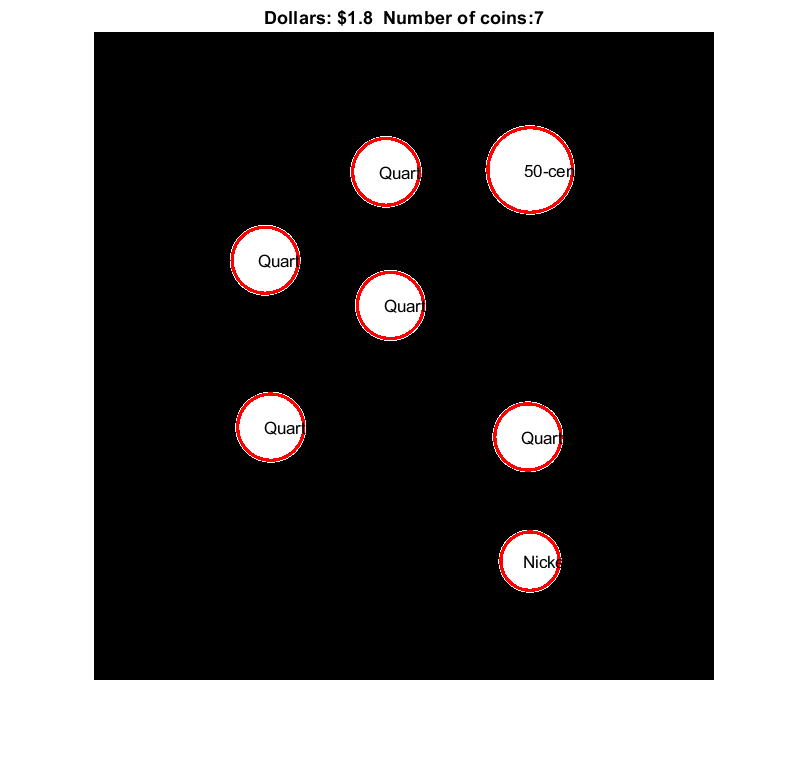

testImageIdx = randi([1,3])

testCoinImage = imread("testCoinImage"+testImageIdx+".png");
figure, imshow(testCoinImage)
[testCoinMask,maskedTestCoinImage]= coinSegmentationv2(testCoinImage);
imshow(maskedTestCoinImage)

imgGauss = imgaussfilt(maskedTestCoinImage,4.5);
imshow(imgGauss)


imgedge5 = edge(imgGauss,"canny",0.066);

%0.0660

figure
imshow(imgedge5)
[BW_out,properties] = filterRegionscircle(imgedge5);
stEL = strel([10,10,10]);
erode5 = imerode(BW_out,stEL);

faceEdgeMask =  erode5 & BW_out ;


figure
imshow(faceEdgeMask)

SE2 = strel("disk",50,8);
truepixelMask = imdilate(faceEdgeMask,SE2);
imshow(truepixelMask)

validCoinMask = truepixelMask & maskedTestCoinImage;
imshow(validCoinMask)

[centers,radii]= imfindcircles(validCoinMask, [20, 100]);
viscircles(centers,radii)

%count number of coins in an image
CC = bwconncomp(validCoinMask)


%segment coin values
[BW_1,properties] = segment_50_cent(validCoinMask);
Bw1 = bwconncomp(BW_1);
Bw11 = cell2mat({Bw1.NumObjects});
[BW_2,properties1] = segment_quarter(validCoinMask);
Bw2 = bwconncomp(BW_2);
Bw22 = cell2mat({Bw2.NumObjects});
[BW_3,properties2] = segment_nickel(validCoinMask);
Bw3 = bwconncomp(BW_3);
Bw33 = cell2mat({Bw3.NumObjects});
[BW_4,properties3] = segment_dime(validCoinMask);
Bw4 = bwconncomp(BW_4);
Bw44 = cell2mat({Bw4.NumObjects});


imgtable = regionprops(validCoinMask,'Area','Centroid','EquivDiameter')
total = 0;


for n=1:size(imgtable,1)
    doll = imgtable(n).Centroid;
    X = doll(1);
    Y = doll(2);
    if imgtable(n).EquivDiameter>101
        str = {'$0.50'};
        text(X-10,Y,str);
        total = total + 0.50;
    elseif (imgtable(n).EquivDiameter > 90 && imgtable(n).EquivDiameter < 101)
        total = total + 0.25;
        str2 = {'$0.25'};
        text(X-10,Y,str2);
    elseif (imgtable(n).EquivDiameter > 80 && imgtable(n).EquivDiameter < 89)
         total = total + 0.05;
        str3 = {'$0.05'};
         text(X-10,Y,str3);
    else
         total = total + 0.10;
         str4 = {'$0.10'};
         text(X-10,Y,str4);
    end
end
 nFiftyCents =  Bw11
 nQuarters = Bw22
 nNickels = Bw33
 nDimes = Bw44



number = n
USD = total
hold on
title(['Dollars: $',num2str(USD),'  ', 'Number of coins:',num2str(n)])










